clear all;clc;

## Load or specify category labels

addpath(genpath('./matlab_functions'))

d = natsortfiles(dir('./behaviorData/shrewData.mat'));
load([d(end).folder,'/',d(end).name])

exp_colors = flipud([179,128,206;...
    211,107,172;...
    254,153,132;...
    248,214,86]/256);

trial_colors = [62,159,44;...
    14,144,201;...
    30,57,155]/256;


## Manipulate data

displayNSess = false;

% Determine which shrews to use
shrewname={'Seymour','Dominic','Ryker'};
shrewID = 1:3;

targ_orig_ID = [40,65,13];
dist_orig_ID = [14,26,87];

allTasks = {'Camel_background_matrix','Camel_v2_test_nn'};

targID = {};
distID = {};
nTarg = {};
nDist = {};
for task = 1:length(allTasks)
    targID{task} = unique(allData.(allTasks{task}).T_Expt_ID);
    distID{task} = unique(allData.(allTasks{task}).D_Expt_ID);
    
    nTarg{task} = length(targID{task});
    nDist{task} = length(distID{task});
end



## Plot performance based on comparable target/distractor objects with and without backgrounds only when T/D on same background

task = 1;

objPerf_cwbg1 = nan(3,3);
for tt = 1:3
    for dd = 1:3
        same_bg = rem(abs(allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).D_Expt_ID),12)==0;
        findTarg = allData.(allTasks{task}).T_Expt_ID<=12*tt;
        findDist = allData.(allTasks{task}).D_Expt_ID<=12*dd;
        objPerf_cwbg1(dd,tt) = mean(allData.(allTasks{task}).correct(same_bg & findTarg & findDist),'omitnan');
    end
end

task = 2;

objPerf_cw1 = nan(3,3);
for tt = 1:3
    for dd = 1:3
        findTarg = allData.(allTasks{task}).T_Expt_ID==targ_orig_ID(tt);
        findDist = allData.(allTasks{task}).D_Expt_ID==dist_orig_ID(dd);
        objPerf_cw1(dd,tt) = mean(allData.(allTasks{task}).correct(findTarg & findDist),'omitnan');
    end
end
[r,p] = corr(objPerf_cw1(:),objPerf_cwbg1(:))

r = -0.0868

p = 0.8243

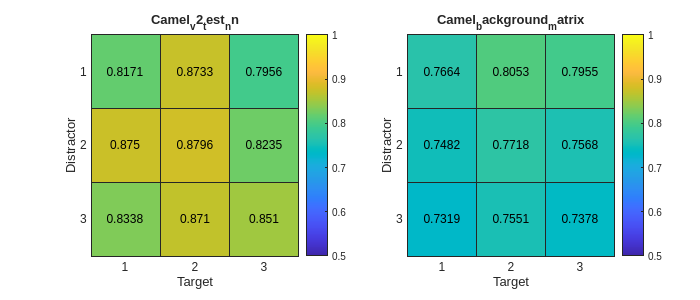

% figure;scatter(objPerf_cw(:),objPerf_cwbg(:),'o')

figure('Renderer', 'painters', 'Position', [10 10 700 300]);
tiledlayout(1,2,"TileSpacing","compact");
nexttile;
heatmap(objPerf_cw1)
colormap("parula");caxis([0.5 1])
title(allTasks{2})
xlabel('Target')
ylabel('Distractor')

nexttile;
heatmap(objPerf_cwbg1)
colormap("parula");caxis([0.5 1])
title(allTasks{1})
xlabel('Target')
ylabel('Distractor')

## Look at relationship of background stats with performance

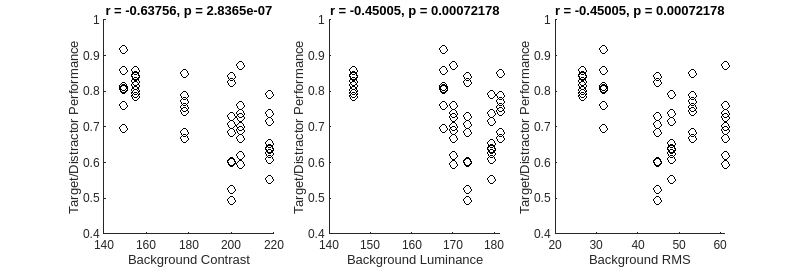

task = 1;
bgID = targID{task}(targID{task}<=12);
nbg = length(bgID);

bgContrast = nan(1,nbg);
bgLuminance = nan(1,nbg);
bgRMS = nan(1,nbg);
objPerf_bg = nan(1,nbg);
for tt = 1:nTarg{task}
    for dd = 1:nDist{task}
        if targID{task}(tt)<=12
            bg_val = targID{task}(tt);
        elseif targID{task}(tt)>12 && targID{task}(tt)<=24
            bg_val = targID{task}(tt)-12;
        elseif targID{task}(tt)>24
            bg_val = targID{task}(tt)-24;
        end
        bg_img = double(imread(['../stimulusSets/Camel_background_matrix/rawBackground/background_',num2str(bg_val),'.png']));
        bgContrast(dd,tt) = max(bg_img,[],'all') - min(bg_img,[],'all');
        bgLuminance(dd,tt) = mean(bg_img,'all');
        bgRMS(dd,tt) = std(bg_img,[],'all');

        same_bg = rem(abs(allData.(allTasks{task}).T_Expt_ID - allData.(allTasks{task}).D_Expt_ID),12)==0;
        findTarg = allData.(allTasks{task}).T_Expt_ID==targID{task}(tt);
        findDist = allData.(allTasks{task}).D_Expt_ID==distID{task}(dd);
        objPerf_bg(dd,tt) = mean(allData.(allTasks{task}).correct(same_bg & findTarg & findDist),'omitnan');
    end
    objPerf_bgtarg(tt) = mean(allData.(allTasks{task}).correct(same_bg & findTarg),'omitnan');
end

figure('Renderer', 'painters', 'Position', [10 10 900 300]);
subplot(1,3,1)
scatter(bgContrast,objPerf_bg,'ko')
[val1,val2] = corr_fun(bgContrast(:),objPerf_bg(:));
[r,p] = corr(val1,val2);
xlabel('Background Contrast')
ylabel('Target/Distractor Performance')
title(['r = ',num2str(r),', p = ',num2str(p)])

subplot(1,3,2)
scatter(bgLuminance,objPerf_bg,'ko')
[val1,val2] = corr_fun(bgLuminance(:),objPerf_bg(:));
[r,p] = corr(val1,val2);
xlabel('Background Luminance')
ylabel('Target/Distractor Performance')
title(['r = ',num2str(r),', p = ',num2str(p)])

subplot(1,3,3)
scatter(bgRMS,objPerf_bg,'ko')
[val1,val2] = corr_fun(bgLuminance(:),objPerf_bg(:));
[r,p] = corr(val1,val2);
xlabel('Background RMS')
ylabel('Target/Distractor Performance')
title(['r = ',num2str(r),', p = ',num2str(p)])

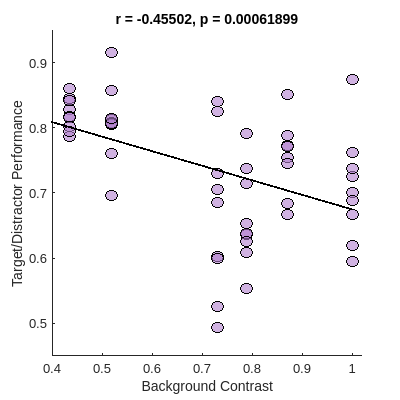

relativeContrast = bgContrast./max(bgContrast,[],'all');
relativeRMS = bgRMS./max(bgRMS,[],'all');
relativeLuminance = bgLuminance./max(bgLuminance,[],'all');

figure('Renderer', 'painters', 'Position', [10 10 400 400]);
scatter(relativeRMS,objPerf_bg,70,'o','filled','MarkerFaceColor',exp_colors(4,:),'MarkerFaceAlpha',0.6,'MarkerEdgeColor','k')
[val1,val2,xfit,yfit] = corr_fun(relativeRMS(:),objPerf_bg(:));
hold on;
plot(xfit,yfit,'k','LineWidth',2)
[r,p] = corr(val1,val2);
xlim([0.4 1.02])
yticks(0.5:0.1:1)
xlabel('Background Contrast')
ylabel('Target/Distractor Performance')
title(['r = ',num2str(r),', p = ',num2str(p)])

## Plot background performance based on background type

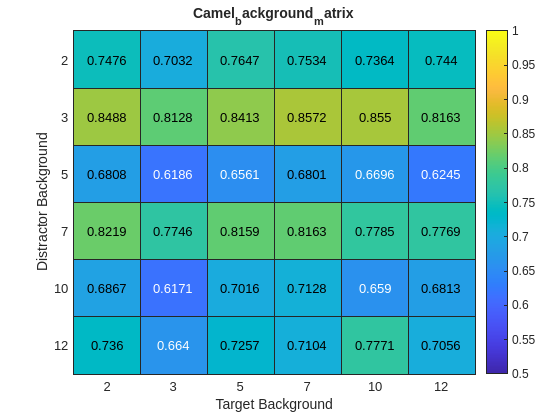

task = 1;
bgID = targID{task}(targID{task}<=12);
nbg = length(bgID);

objPerf_bg = nan(nbg,nbg);
for tt = 1:nbg
    for dd = 1:nbg
        findTarg = mod(allData.(allTasks{task}).T_Expt_ID-bgID(tt),12)==0;
        findDist = mod(allData.(allTasks{task}).D_Expt_ID-bgID(dd),12)==0;
        objPerf_bg(dd,tt) = mean(allData.(allTasks{task}).correct(findTarg & findDist),'omitnan');
    end
end

figure();
heatmap(bgID,bgID,objPerf_bg)
colormap("parula");caxis([0.5 1])
title(allTasks{1})
xlabel('Target Background')
ylabel('Distractor Background')

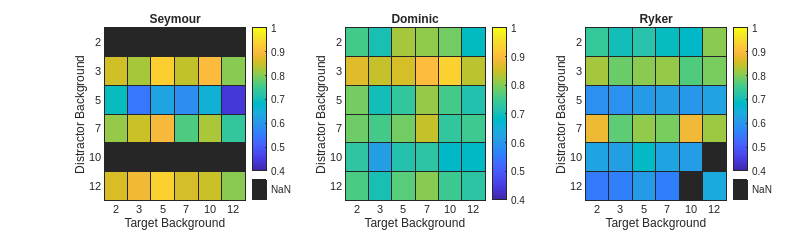


task = 1;
bgID = targID{task}(targID{task}<=12);
nbg = length(bgID);

objPerf_bg_shrew = {};
for ts = 1:3
    for tt = 1:nbg
        for dd = 1:nbg
            findTarg = mod(allData.(allTasks{task}).T_Expt_ID-bgID(tt),12)==0;
            findDist = mod(allData.(allTasks{task}).D_Expt_ID-bgID(dd),12)==0;
            objPerf_bg_shrew{ts}(dd,tt) = mean(allData.(allTasks{task}).correct(findTarg & findDist & allData.(allTasks{task}).ShrewID==ts),'omitnan');
        end
    end
end

figure('Renderer', 'painters', 'Position', [10 10 1000 300]);
tiledlayout(1,3,"TileSpacing","compact");
for ts = 1:3
    nexttile;
    heatmap(bgID,bgID,objPerf_bg_shrew{ts})
    colormap("parula");caxis([0.4 1])
    xlabel('Target Background')
    ylabel('Distractor Background')
    title(shrewname{ts})
end

## Plot performance for ALL targets and distractors

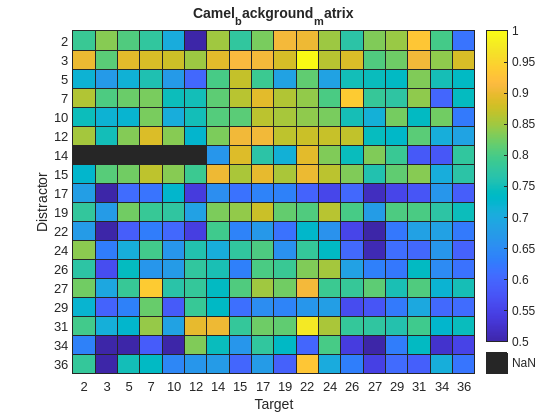

task = 1;

objPerf_all = nan(length(distID{task}),length(targID{task}));
for tt = 1:length(targID{task})
    for dd = 1:length(distID{task})
        findTarg = allData.(allTasks{task}).T_Expt_ID==targID{task}(tt);
        findDist = allData.(allTasks{task}).D_Expt_ID==distID{task}(dd);
        objPerf_all(dd,tt) = mean(allData.(allTasks{task}).correct(findTarg & findDist),'omitnan');
    end
end

figure();
heatmap(distID{task},targID{task},objPerf_all)
colormap("parula");caxis([0.5 1])
title(allTasks{1})
xlabel('Target')
ylabel('Distractor')